clear;clc;

## setup viewer

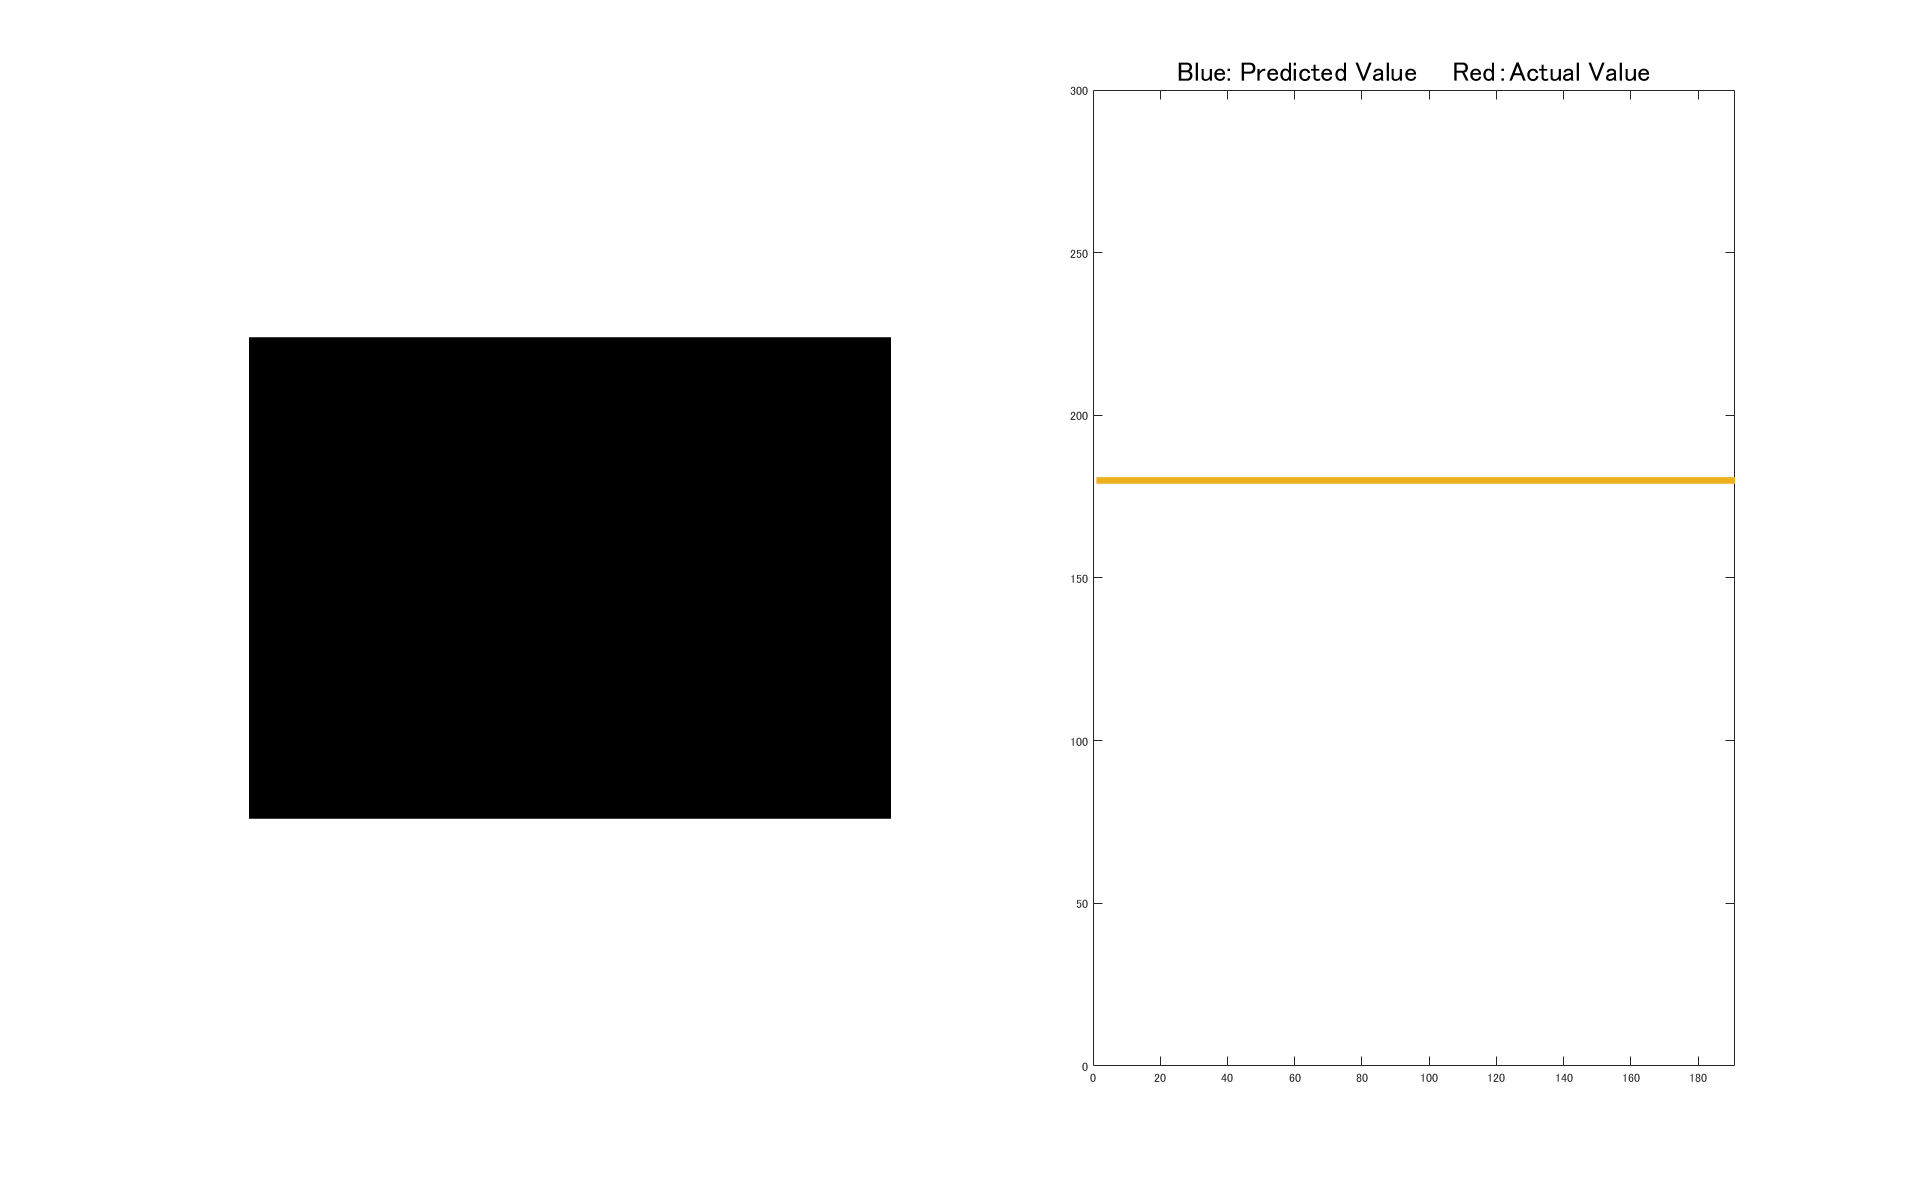

reader = VideoReader('movie.mp4');
load myNet; load speedcurve
n=0;
valueall =[];
S = get(0, 'ScreenSize');
figure('Position', S);
subplot(1,2,1),h=imshow(uint8(zeros(480,640,3)));t=title("",'FontSize',30);
subplot(1,2,2),
p1 = plot(0,'LineWidth',5);xlim([0 191]);ylim([0 300]),title("Blue: Predicted Value　　Red：Actual Value",'FontSize',20);
hold on
p2 = plot(0,'LineWidth',3);xlim([0 191]);ylim([0 300]);
plot([1 191],[180 180],'LineWidth',5);
hold off

## show the result

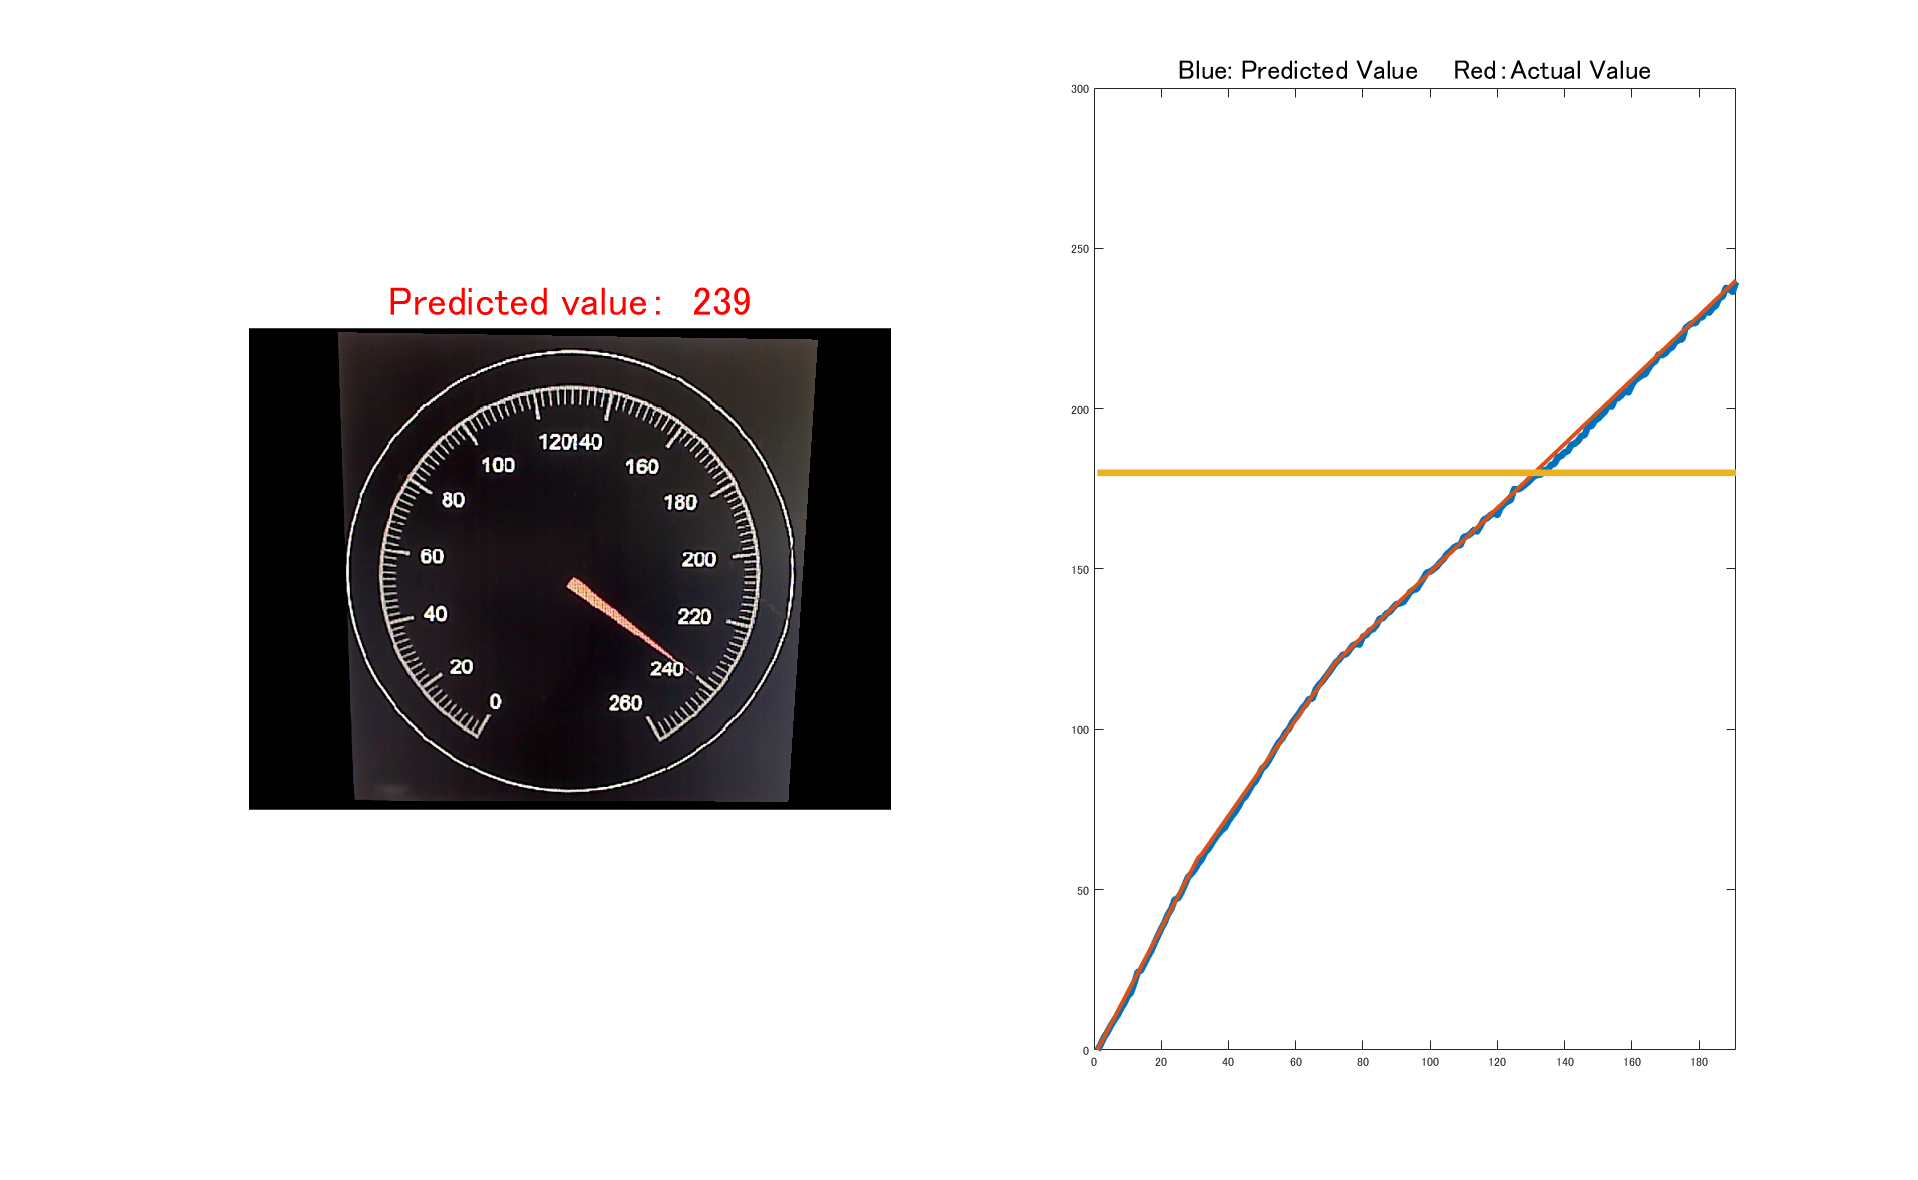

while hasFrame(reader)
    n=n+1;
    I = readFrame(reader);
    I2 = imresize(I,[227 227]);
    value = predict(myNet,I2);
    if value > 180
        t.Color = 'r';
    end
    t.String= "Predicted value：  " + num2str(int16(value));
    valueall = [valueall value];
    h.CData = I;
    p1.YData = valueall(1:n);
    p2.YData = speedcurve(1:n);
    drawnow;shg
end

*Copyright 2019 The MathWorks, Inc.*